T=10;
N=50;
h=T/N;
u0=[1;1/2]

u0 =     1.0000
    0.5000


f(3,u0)

ans =    -2.4383
   -3.1979


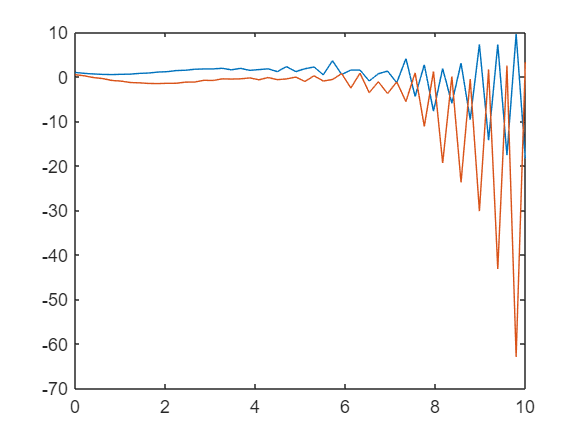

X=zeros(2,N);
X(:,1)=u0;
X(:,2)=u0+h*f(0,u0);
t=linspace(0,T,N);
for i=2:(N-1)
    X(:,i+1)=0.1.*X(:,i)+0.9*X(:,i-1)+h.*(1.95*f(t(i),X(:,i))-0.05.*f(t(i-1),X(:,i-1)));
end
plot(t,X(1,:),t,X(2,:))

X(:,N)

ans =   -18.3118
    3.3312


3

P=zeros(2,5)

P =      0     0     0     0     0
     0     0     0     0     0


P(1,:)=[50,100,200,500,1000]

P =           50         100         200         500        1000
           0           0           0           0           0


j=1

j = 1

for N=P(1,:)
    T=10;
    h=T/N;
    v0=[0;1];
    V=zeros(2,N);
    V(:,1)=v0;
    V(:,2)=v0+h*f(0,v0);
    t=linspace(0,T,N);
    for i=2:(N-1)
        V(:,i+1)=0.1.*V(:,i)+0.9*V(:,i-1)+h.*(1.95*g(t(i),V(:,i))-0.05.*g(t(i-1),V(:,i-1)));
    end
    %plot(t,V(1,:),t,V(2,:),t,cos(t))
    V(:,N);
    
    M=0;
    for i=1:N
        if abs(V(2,i)-cos(t(i)))>M
            M=abs(V(2,i)-cos(t(i)))
        end
    end
    P(2,j)=M
    j=j+1;
end

M = 1.4666

P = 	1.0e+03 *

    0.0500    0.1000    0.2000    0.5000    1.0000
    0.0015         0         0         0         0


M = 0.7386

P = 	1.0e+03 *

    0.0500    0.1000    0.2000    0.5000    1.0000
    0.0015    0.0007         0         0         0


M = 0.3706

P = 	1.0e+03 *

    0.0500    0.1000    0.2000    0.5000    1.0000
    0.0015    0.0007    0.0004         0         0


M = 0.1485

P = 	1.0e+03 *

    0.0500    0.1000    0.2000    0.5000    1.0000
    0.0015    0.0007    0.0004    0.0001         0


M = 0.0743

P = 	1.0e+03 *

    0.0500    0.1000    0.2000    0.5000    1.0000
    0.0015    0.0007    0.0004    0.0001    0.0001


P

P = 	1.0e+03 *

    0.0500    0.1000    0.2000    0.5000    1.0000
    0.0015    0.0007    0.0004    0.0001    0.0001


p=polyfit(P(1,:),P(2,:),5)

p =     0.0000   -0.0000    0.0000   -0.0011    0.0722         0


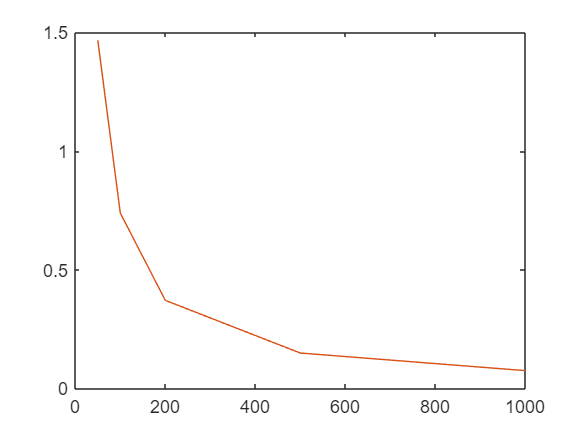

plot(P(1,:),P(2,:),P(1,:),polyval(p,P(1,:)))

function v=f(t,u)
v=[-u(1)-t*sin(u(2));-2*(1+exp(u(2))-(1+exp(-t))*u(1))];
end
function a=g(t,u)
a=[-u(2);u(1)];
end
function b=c(x)
A=[3,4;6,0;7,6;1,7];
B=[-5;9;-3;-6];
b=norm(A*x-B)^2
end
